# MIP Calculator

Code explained [here](https://onedrive.live.com/view.aspx?resid=6734D084BA63FB2%21487&id=documents&wd=target%28Doublepass%20%28xDBL%20xGTS%5C%29.one%7CA0379185-A565-4240-A5C4-68F4755BFB4B%2FMembrane%20Phase%20Object%20Calculations%7C9B3E84CD-6EF2-48BF-B756-7DEEDF289206%2F%29 onenote:https://d.docs.live.net/06734d084ba63fb2/Documents/Research/Doublepass%20(xDBL%20xGTS).one#Membrane%20Phase%20Object%20Calculations&section-id={A0379185-A565-4240-A5C4-68F4755BFB4B}&page-id={9B3E84CD-6EF2-48BF-B756-7DEEDF289206}&end)

From Riemer:

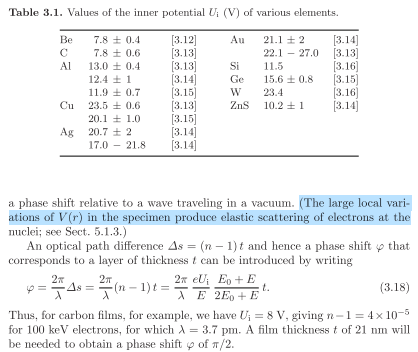

Where E is the electron energy, E_o the electron rest energy

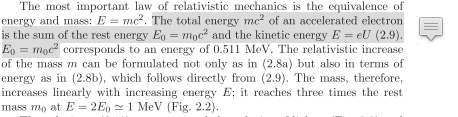

From hyperphysics

A dedicated paper claims:

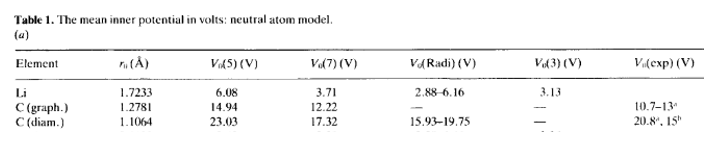

#### Verification

Wavelength verfified with hyperphysics comparison at 3 and 10 keV

Phase verified with Reimer example:

## Simple analysis

addpath('C:\Users\johns\Documents\Github\QEM-MATLAB');
load ImpVariables.mat;
KE = 1*c.kilo;
lambda = electronWavelength(KE)

pc = 3.1984e+04

lambda = 3.8764e-11

lambda = 3.8764e-11

cd('C:\Users\johns\Documents\Github\QEM-MATLAB\Phase Objects and Diffraction Calc');

## Phase Object Strength

thickness = [0.355] * c.nano; % film thickness in nm
innerPot = [13.24]; %eV
deltaPhase = 2*pi/lambda * (innerPot/KE) *...
    ((c.eRestMass_eV+KE)/(2*c.eRestMass_eV+KE)) * thickness

deltaPhase = 0.3813

deltaPhasePiOver2 = deltaPhase*2/pi

deltaPhasePiOver2 = 0.2427

## Diffraction

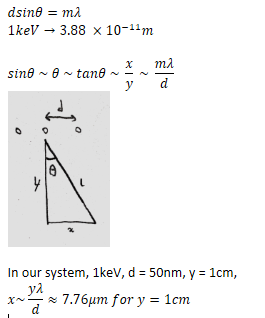

clf
%hold on
d =  [100]*c.nano; % 0.246 for graphene
y = 10*c.milli;

KE = [0.5:0.25:5]*c.kilo;
lambda = electronWavelength(KE);

pc = 	1.0e+04 *

    2.2611    2.7696    3.1984    3.5764    3.9182    4.2327    4.5255    4.8006    5.0609    5.3085    5.5453    5.7724    5.9910    6.2021    6.4062    6.6042    6.7965    6.9836    7.1659


lambda = 	1.0e+-10 *

    0.5483    0.4477    0.3876    0.3467    0.3164    0.2929    0.2740    0.2583    0.2450    0.2336    0.2236    0.2148    0.2069    0.1999    0.1935    0.1877    0.1824    0.1775    0.1730


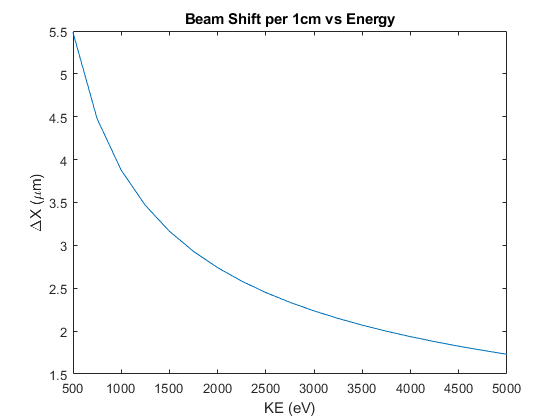

deltaX = y*lambda/d;
plot(KE, deltaX/c.micro); xlabel("KE (eV)"); ylabel("{\Delta}X (\mum)")
title("Beam Shift per 1cm vs Energy")

theta = asin(lambda/d)*180/(pi);
